clear all
close all
clc
beep off
pm_addunit('percent', 0.01, '1');
options = bodeoptions;
options.FreqUnits = 'Hz';

tc = 1e-4;
f = 50;
T = 1/f;
Np = floor(T/tc/2);
len = 6*T;
Nc = floor(len/tc);

time = [0:tc:len-tc];
theta = time*2*pi*f;

U1 = 1;
depth1 = 0.25;
depth2 = 0.5;
U2 = U1 - depth1;
U3 = U1 - depth2;

phi_1 = 0;
% phi_2 = - 2*atan(1/sqrt((2*U2-1)/(2*U2+1)));
% phi_3 = 2*atan(1/sqrt((2*U2-1)/(2*U2+1)));

phi_2 = 2*atan(sqrt(-U2^2-2*U2+U3^2-1)/sqrt(U2^2-2*U2-U3^2+1))

phi_2 =      2.636232143305636e+00

phi_3 = 2*atan((U2-U3-1)/(U2-U3+1)*sqrt(-U2^2-2*U2+U3^2-1)/sqrt(U2^2-2*U2-U3^2+1))

phi_3 =     -2.328837092221133e+00

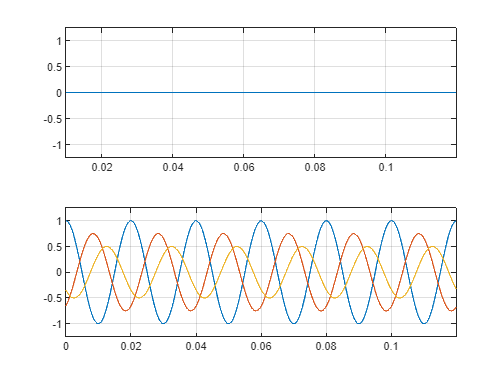


u1 = U1 * cos(theta - phi_1);
u2 = U2 * cos(theta - phi_2);
u3 = U3 * cos(theta - phi_3);

u0 = 1/3*(u1+u2+u3);

figure; 
subplot 211; 
plot(time, u0); 
set(gca, 'ylim',[-1.25 1.25]);
set(gca, 'xlim',[time(Np) time(end)]);
grid on
subplot 212; 
plot(time, u1,time, u2,time, u3); 
set(gca, 'ylim',[-1.25 1.25]);
set(gca, 'xlim',[time(1) time(end)]);
grid on

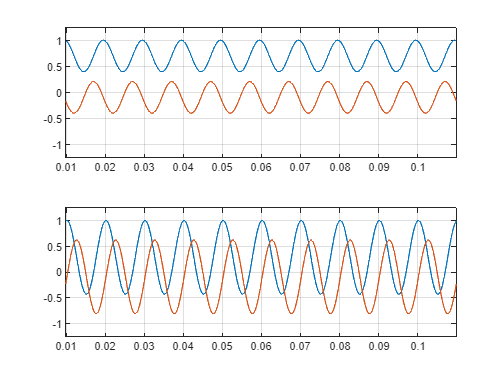


ualpha = 2/3*(u1 - 0.5*u2 - 0.5*u3);
ubeta = 2/3*(sqrt(3)/2*u2 - sqrt(3)/2*u3);

udp = ualpha.*cos(theta) + ubeta.*sin(theta);
uqp = -ualpha.*sin(theta) + ubeta.*cos(theta);

udn = ualpha.*cos(theta) - ubeta.*sin(theta);
uqn = ualpha.*sin(theta) + ubeta.*cos(theta);

figure; 
subplot 211; 
plot(time, udp, time, uqp); 
set(gca, 'ylim',[-1.25 1.25]);
set(gca, 'xlim',[time(Np) time(Nc-Np)]);
grid on
subplot 212; 
plot(time, udn, time, uqn); 
set(gca, 'ylim',[-1.25 1.25]);
set(gca, 'xlim',[time(Np) time(Nc-Np)]);
grid on

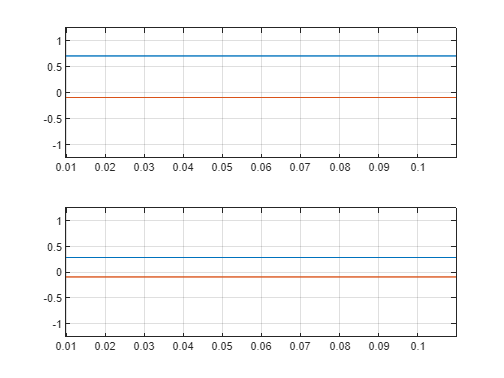


udp_mean = movmean(udp,Np);
uqp_mean = movmean(uqp,Np);
udn_mean = movmean(udn,Np);
uqn_mean = movmean(uqn,Np);

figure; 
subplot 211; 
plot(time, udp_mean, time, uqp_mean); 
set(gca, 'ylim',[-1.25 1.25]);
set(gca, 'xlim',[time(Np) time(Nc-Np)]);
grid on
subplot 212; 
plot(time, udn_mean, time, uqn_mean); 
set(gca, 'ylim',[-1.25 1.25]);
set(gca, 'xlim',[time(Np) time(Nc-Np)]);
grid on